### 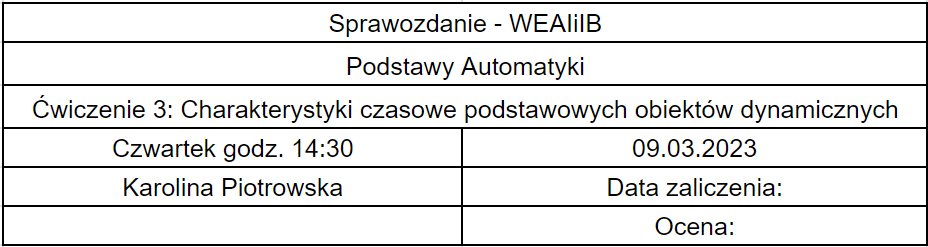

## Cele ćwiczenia

Ćwiczenie miało na celu wyznaczenie odpowiedzi czasowych podstawowych obiektów dynamicznych na określone wymuszenia - skok jednostowy i deltę Diraca. Wykorzystane do tego zostało oprogramowanie Matlab.

## Przebieg laboratorium

### Obiekt inercyjny I rzędu

Sygnał wyjściowy członu inercyjnego staje się proporcjonalny do sygnału wejściowego dopiero po upływie pewnego czasu. Obiekty te charakteryzują się magazynowaniem energii i stałą czasową. 

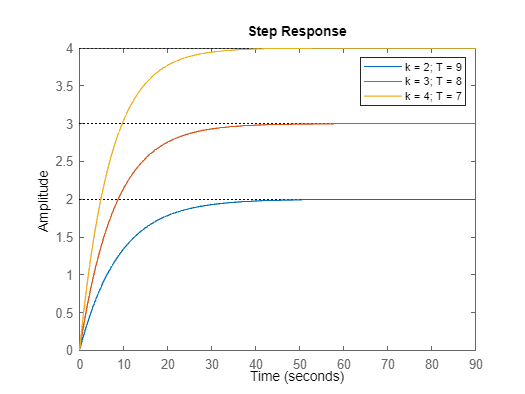

k1 = 2;
T1 = 9;
k2 = 3;
T2 = 8;
k3 = 4;
T3 = 7;

licz1 = [0, k1];
mian1 = [T1, 1];
licz2 = [0, k2];
mian2 = [T2, 1];
licz3 = [0, k3];
mian3 = [T3, 1];

step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
legend('k = 2; T = 9', 'k = 3; T = 8', 'k = 4; T = 7')

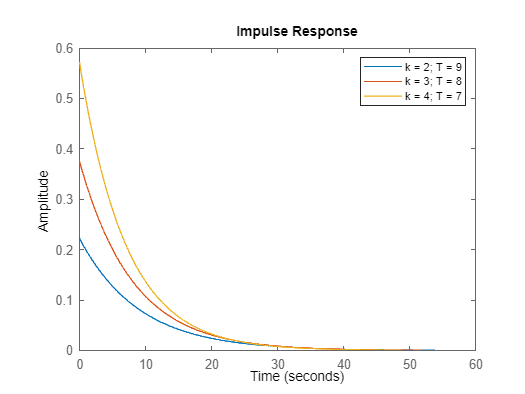


impulse(licz1, mian1)
hold on
impulse(licz2, mian2)
impulse(licz3, mian3)
hold off
legend('k = 2; T = 9', 'k = 3; T = 8', 'k = 4; T = 7')

### Obiekt inercyjny II rzędu

Ten człon składa się z dwóch połączonych szeregowo obiektów inercyjnych I rzędu.

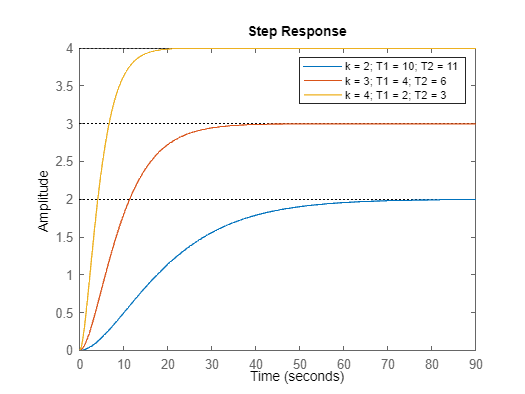

T11 = 10;
T12 = 11;
T21 = 4;
T22 = 6;
T31 = 2;
T32 = 3;

licz1 = [k1];
licz2 = [k2];
licz3 = [k3];

mian1 = [T11*T12, T11 + T12, 1];
mian2 = [T21*T22, T21 + T22, 1];
mian3 = [T31*T32, T31 + T32, 1];

step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
legend('k = 2; T1 = 10; T2 = 11', 'k = 3; T1 = 4; T2 = 6', 'k = 4; T1 = 2; T2 = 3')

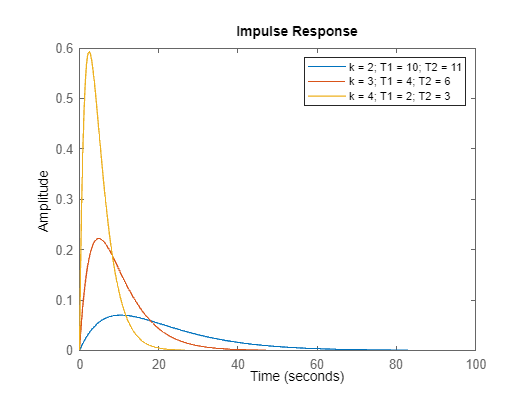


impulse(licz1, mian1)
hold on
impulse(licz2, mian2)
impulse(licz3, mian3)
hold off
legend('k = 2; T1 = 10; T2 = 11', 'k = 3; T1 = 4; T2 = 6', 'k = 4; T1 = 2; T2 = 3')

### Obiekt oscylacyjny II rzędu

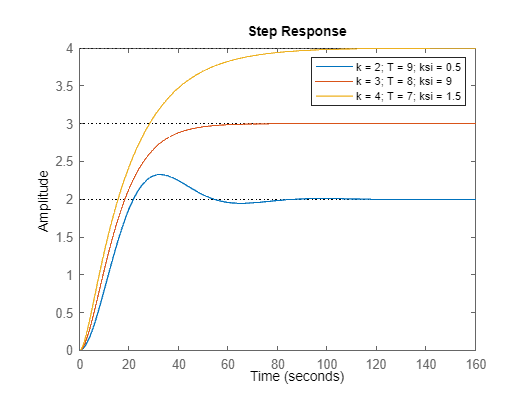

ksi1 = 0.5;
ksi2 = 1;
ksi3 = 1.5;

mian1 = [T1^2, 2*ksi1*T1, 1];
mian2 = [T2^2, 2*ksi2*T2, 1];
mian3 = [T3^2, 2*ksi3*T3, 1];

step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
legend('k = 2; T = 9; ksi = 0.5', 'k = 3; T = 8; ksi = 9', 'k = 4; T = 7; ksi = 1.5')

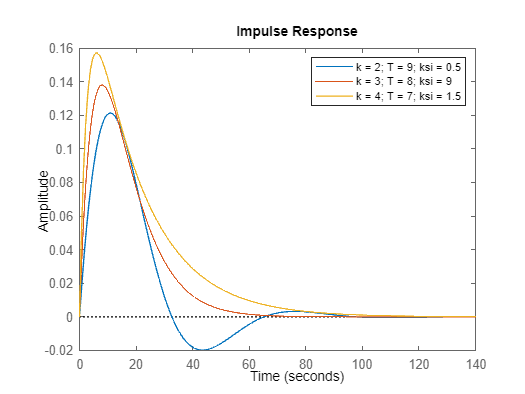


impulse(licz1, mian1)
hold on
impulse(licz2, mian2)
impulse(licz3, mian3)
hold off
legend('k = 2; T = 9; ksi = 0.5', 'k = 3; T = 8; ksi = 9', 'k = 4; T = 7; ksi = 1.5')

### Obiekt całkujący z inercją I rzędu

Jego sygnał wyjściowy jest proporcjonalny do całki sygnału wejściowego.

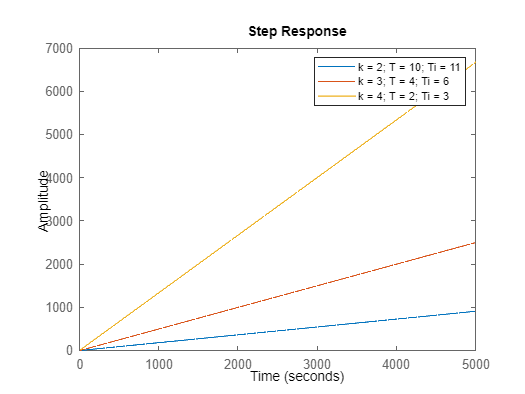

mian1 = [T11*T12, T12, 0];
mian2 = [T21*T12, T22, 0];
mian3 = [T31*T32, T32, 0];

step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
legend('k = 2; T = 10; Ti = 11', 'k = 3; T = 4; Ti = 6', 'k = 4; T = 2; Ti = 3')

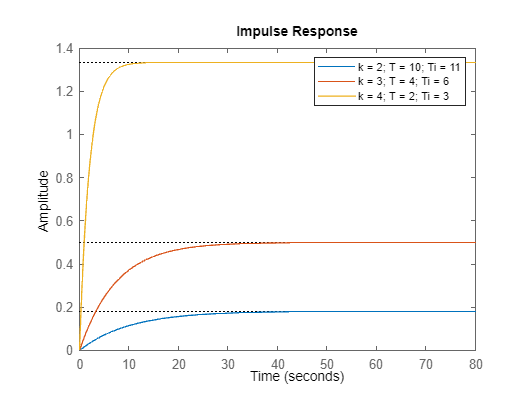


impulse(licz1, mian1)
hold on
impulse(licz2, mian2)
impulse(licz3, mian3)
hold off
legend('k = 2; T = 10; Ti = 11', 'k = 3; T = 4; Ti = 6', 'k = 4; T = 2; Ti = 3')

### Obiekt różniczkujący rzeczywisty 

Jego sygnał wyjściowy jest proporcjonalny do pochodnej sygnału wejściowego.

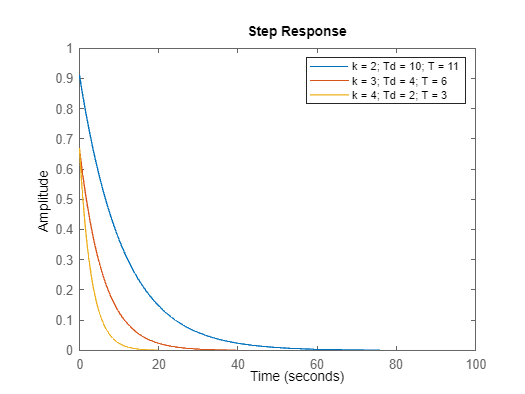

licz1 = [T11, 0];
licz2 = [T21, 0];
licz3 = [T31, 0];

mian1 = [T12, 1];
mian2 = [T22, 1];
mian3 = [T32, 1];

step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
legend('k = 2; Td = 10; T = 11', 'k = 3; Td = 4; T = 6', 'k = 4; Td = 2; T = 3')

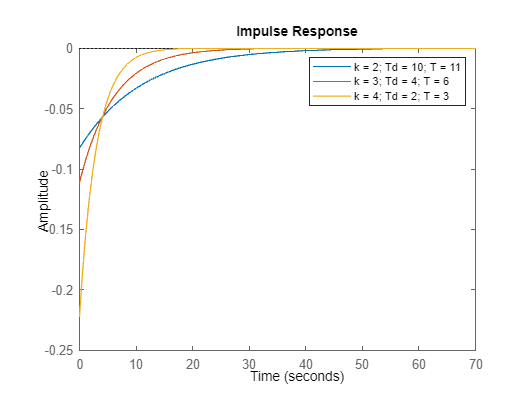


impulse(licz1, mian1)
hold on
impulse(licz2, mian2)
impulse(licz3, mian3)
hold off
legend('k = 2; Td = 10; T = 11', 'k = 3; Td = 4; T = 6', 'k = 4; Td = 2; T = 3')

### Obiekt inercyjny I rzędu z opóźnieniem

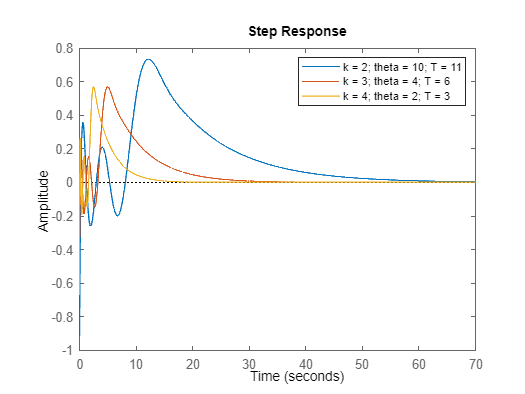

n = 5;

[del_l1, del_m1] = pade(T11, n);
[del_l2, del_m2] = pade(T21, n);
[del_l3, del_m3] = pade(T31, n);

mian1 = [T12, 1];
mian2 = [T22, 1];
mian3 = [T32, 1];

[licz_d1, mian_d1] = series(del_l1, del_m1, licz1, mian1);
[licz_d2, mian_d2] = series(del_l2, del_m2, licz2, mian2);
[licz_d3, mian_d3] = series(del_l3, del_m3, licz3, mian3);

step(licz_d1, mian_d1)
hold on
step(licz_d2, mian_d2)
step(licz_d3, mian_d3)
hold off
legend('k = 2; theta = 10; T = 11', 'k = 3; theta = 4; T = 6', 'k = 4; theta = 2; T = 3')

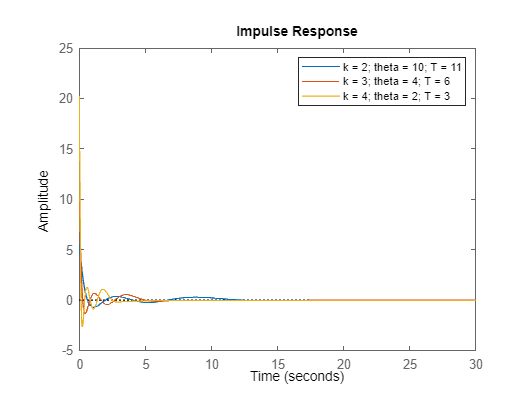


impulse(licz_d1, mian_d1)
hold on
impulse(licz_d2, mian_d2)
impulse(licz_d3, mian_d3)
hold off
legend('k = 2; theta = 10; T = 11', 'k = 3; theta = 4; T = 6', 'k = 4; theta = 2; T = 3')

### Wnioski

Ćwiczenie było nietrudne, ponadto wykonywaliśmy bliźniaczo podobne na laboratorium z Modelowania Systemów Dynamicznych w poprzednim semestrze. Ilustrowanie trzech obiektów tego samego typu lecz o różnych parametrach na jednym wykresie uwydatnia wpływ poszczególnych parametrów na wynik końcowy; szczególnie dokładnie można zaobserwować wartości wzmocnienia i stałej czasowej na wykresie obiektu inercyjnego I rzędu. W przypadku obiektu inercyjnego I rzędu z opóźnieniem oscylacje wynikają z wysokiego rzędu aproksymacji (n=5). 